Load equations and symbols from file

load symbols.mat
load CoreEquations.mat
load DesignParameters.mat

Calculate torque requirements for different movements

%Stage 1: Lifting against step from ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == -rw; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol1 = mysolver(Eqns);
sol1.T_z/2

$$ans = 0.51610715833524464766666016290434$$

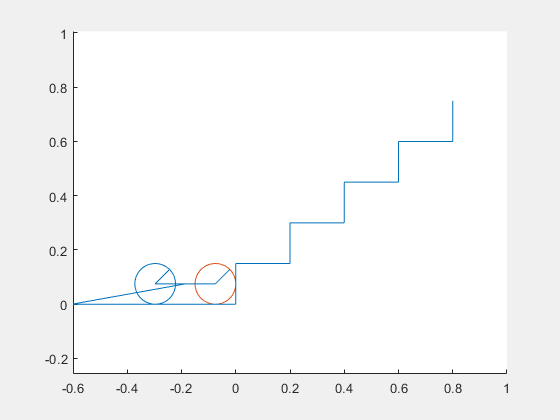

%Draw positions
drawfigure(sol1);

% sol = sol1
% f=figure('visible','on');
% hold on;
% %wheels
% circle(sol.s61, sol.s62, sol.rw);
% line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
% 
% circle(sol.s51, sol.s52, sol.rw);
% line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
% 
% %frame
% line([sol.s51,sol.s61],[sol.s52,sol.s62])
% 
% %Tail
% line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
% figure
% axis equal;
% axis on;
% ax = gca;
% ax.XAxisLocation = 'origin';
% ax.YAxisLocation = 'origin';
% xlim([-0.7,0.7])
% %ylim([-0.1, 0.5])
% %step
% corner(:,1) = [sol.step_start1-10; sol.step_start2];
% for i= 1:5
%     corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
%     corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
% end
% line(corner(1,:), corner(2,:))
% hold off;

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    s62 == rw; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

[sol2, unsolved] = mysolver(Eqns, 1);
sol2.T_z

$$ans = 0.61008213118996576714703401817655$$

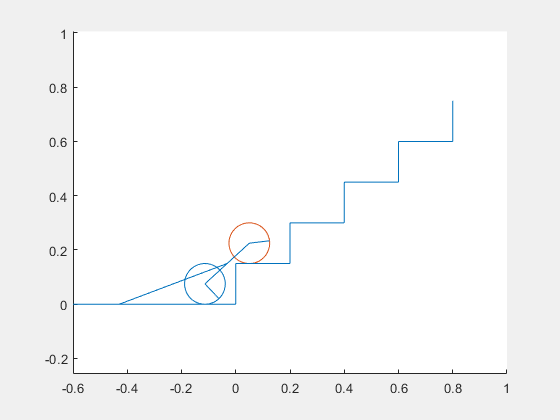

drawfigure(sol2);

%Stage 3: Pulling up step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 1.0318324517692120818866178792499$$

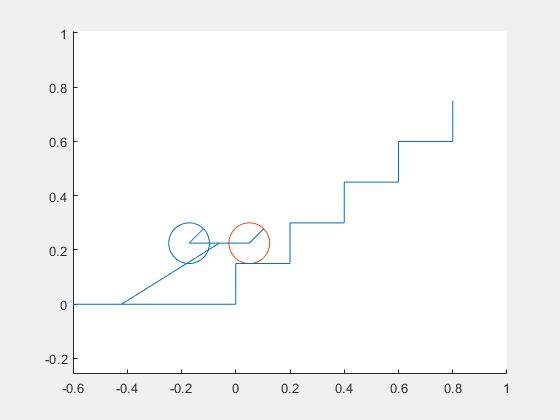

drawfigure(sol3);

%Stage 1: Lifting against step from first step with tail on ground, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw; s52 == rw+step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    pi/2 < t73; t73 < pi;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol3 = mysolver(Eqns);
sol3.T_z

$$ans = 1.0320111151362721718219742391349$$

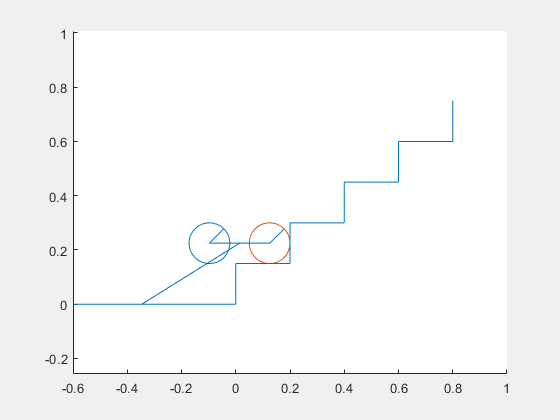

drawfigure(sol3);

%Stage 6: Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-rw-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    s62 == rw+step_height; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol4 = mysolver(Eqns);
sol4.T_z

$$ans = 0.724251083466133176710941408096$$

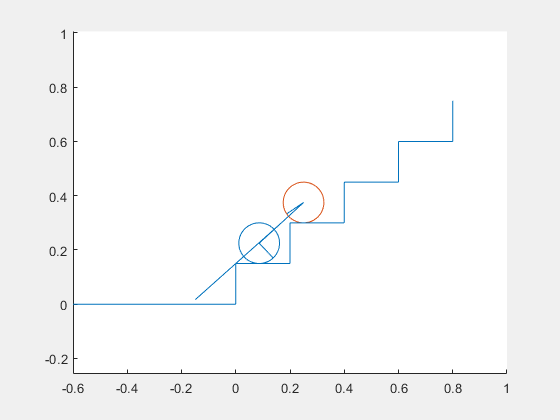

drawfigure(sol4);

%Stage 6:Pulling up step with tail on step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];

sol5 = mysolver(Eqns);
sol5.T_z

$$ans = 1.3730470710456295975853259189471$$

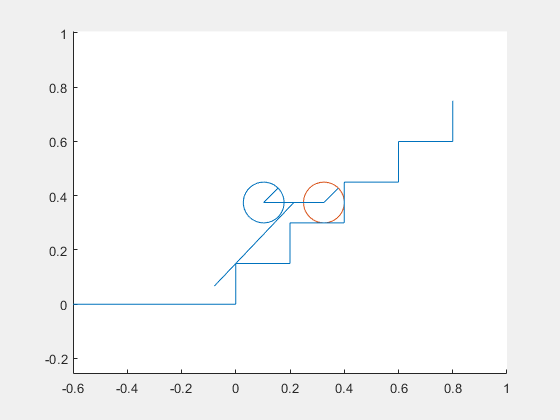

drawfigure(sol5);

%Stage 4:Lifting against step from second step with tail on first step, calculate stall torque
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t13 == 0; t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
sol6 = mysolver(Eqns);
sol6.T_z

$$ans = 1.2503645710814432997455546716659$$

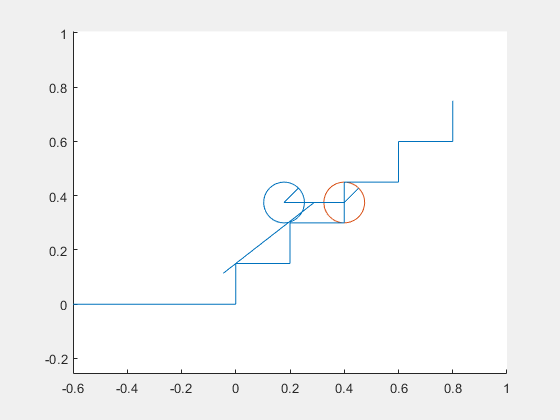

drawfigure(sol6);

%Test stall torques across stage 1 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
      C_friction7: 0.2
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
    L_body_centre: 0.0437
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              a11: 0.0
              a12: 0.0
              a13: 0.0
              a21: 0.0
              a22: 0.0
              a23: 0.0
              a31: 0.0
              a32: 0.0
              a33: 0.0
              a41: 0.0
              a42: 0.0
              a4

solutions1 = []


solutions1 =

     []



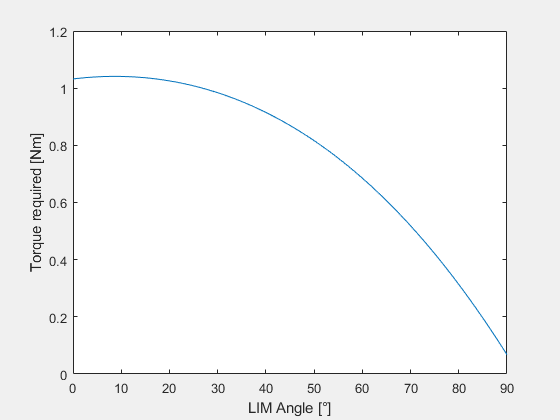

for i = linspace(0, pi/2, 100)
    solutions1 = [solutions1; mysolver([unsolved; t13 == i; t23 == 0;], 1, sol)];
end

for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    thetarange(i) =solutions1(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 3 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == step_width-rw-0.075; s52 == rw+step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
      C_friction7: 0.2
        F_react53: 0.0
        F_react61: 0.0
        F_react62: 0.0
        F_react63: 0.0
        F_react73: 0.0
               I1: 0.0015369319646590562551680125835674
               I2: 0.000068751841737150920660058550648586
               I3: 0.000013375817588925833023587828873868
               I4: 0.000013375817588925833023587828873868
               I5: 0.00012233851720283331582055097452866
               I6: 0.00012233851720283331582055097452866
               I7: 0.0032796810000000000025199842212942
    L_body_centre: 0.0437
        M_react61: 0.0
        M_react62: 0.0
        M_react63: 0.0
          N_idler: 33.0
         N_planet: 16.0
            N_sun: 50.0
              a13: 0.0
              a23: 0.0
              a33: 0.0
              a43: 0.0
              a52: 0.0
              a53: 0.0
              a62: 0.0
              a63: 0.0
              a73: 0.0
              f23: 0.0
              f33: 0.0
              f4

solutions3 = []


solutions3 =

     []



for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions3 = [solutions3; mysolver([unsolved; t13 == i; t23 == 0;], 1, sol)];
    solutions3(end).T_z
end

$$ans = 0.61008213118996574758525847510223$$

$$ans = 0.61491367058363019133110062214133$$

$$ans = 0.61973483149618711960229133477715$$

$$ans = 0.62454562339893229209434633569858$$

$$ans = 0.6293460539526989101599536840608$$

$$ans = 0.63413612899822595351189595499771$$

$$ans = 0.63891585254636616669709195750087$$

$$ans = 0.64368522676813036673649170810129$$

$$ans = 0.64844425198456923611418350419782$$

$$ans = 0.65319292665648917408502571316815$$

$$ans = 0.657931247374003181694743697907$$

$$ans = 0.66265920884591374459738969039203$$

$$ans = 0.66737680388892716641153900865365$$

$$ans = 0.67208402341669817865741130773372$$

$$ans = 0.67678085642870310661227228997564$$

$$ans = 0.68146728999893981826671985139093$$

$$ans = 0.68614330926445311514886726970793$$

$$ans = 0.69080889741368471395584127499263$$

$$ans = 0.69546403567464441494798011804943$$

$$ans = 0.70010870330290287295248410525129$$

$$ans = 0.70474287756940196669295072327885$$

$$ans = 0.70936653374808305034180485087178$$

$$ans = 0.71397964510332944625541979182415$$

$$ans = 0.71858218287722195638499917289628$$

$$ans = 0.7231741162766055465759075682967$$

$$ans = 0.72775541245996481225903540408339$$

$$ans = 0.73232603652410577018497374135515$$

$$ans = 0.73688595149064192779239799495769$$

$$ans = 0.74143511829228304437054337969771$$

$$ans = 0.74597349575892249239323673288402$$

$$ans = 0.75050104060352283520264062156895$$

$$ans = 0.75501770740779490876737430815927$$

$$ans = 0.75952344860766985658880411340009$$

$$ans = 0.76401821447855971959006399819679$$

$$ans = 0.76850195312040448549606247667519$$

$$ans = 0.77297461044250313622513129673501$$

$$ans = 0.77743613014812477947490865081366$$

$$ans = 0.78188645371889745624217339860152$$

$$ans = 0.78632552039897118690342742172044$$

$$ans = 0.79075326717895221558178500716983$$

$$ans = 0.79516962877960458606926922400491$$

$$ans = 0.79957453763531622676933350184714$$

$$ans = 0.8039679238773254607566775929788$$

$$ans = 0.80834971531670443380179302999293$$

$$ans = 0.81271983742709560452325761712381$$

$$ans = 0.81707821332719735114034562013553$$

$$ans = 0.82142476376299462215259659310859$$

$$ans = 0.82575940708973039431501990083547$$

$$ans = 0.83008205925361382093636061898279$$

$$ans = 0.83439263377325991363406254375413$$

$$ans = 0.83869104172085721702974040206639$$

$$ans = 0.84297719170305776076109631025891$$

$$ans = 0.84725098984158457304415814240109$$

$$ans = 0.85151233975355183814136823904864$$

$$ans = 0.85576114253149263524255179861231$$

$$ans = 0.85999729672308785298223634199965$$

$$ans = 0.86422069831059192855419376011321$$

$$ans = 0.868431240689948251535153532469$$

$$ans = 0.87262881464958948049621440657034$$

$$ans = 0.87681330834891561382578236810669$$

$$ans = 0.88098460729644335597756344229504$$

$$ans = 0.88514259432762092495993332947321$$

$$ans = 0.8892871495823005047186226922781$$

$$ans = 0.89341815048186139304895924839117$$

$$ans = 0.89753547170597660550881778018818$$

$$ans = 0.90163898516901545678841807406816$$

$$ans = 0.9057285599960733014606267315289$$

$$ans = 0.90980406249862104066717073685352$$

$$ans = 0.91386535614976562921842950276461$$

$$ans = 0.91791230155911248359411433932179$$

$$ans = 0.92194475644722079336056203921486$$

$$ans = 0.9259625756196419823542617541939$$

$$ans = 0.92996561094053228990336225579365$$

$$ans = 0.93395371130582772562094339025505$$

$$ans = 0.9379267226159726386865507047307$$

$$ans = 0.94188448774818900814832969811172$$

$$ans = 0.94582684652827688308212664337568$$

$$ans = 0.94975363570193266958539596201054$$

$$ans = 0.95366468890557359047740125993704$$

$$ans = 0.95755983663665616697318308806656$$

$$ans = 0.96143890622347406874551342577414$$

$$ans = 0.96530172179442342926163659080013$$

$$ans = 0.969148104246719566590618820961$$

$$ans = 0.97297787121455220050026825160904$$

$$ans = 0.97679083703666203060084889361051$$

$$ans = 0.98058681272332461747625335124396$$

$$ans = 0.98436560592272326970509469092057$$

$$ans = 0.98812702088669558401525589081633$$

$$ans = 0.99187085843583447605923950833099$$

$$ans = 0.99559691592392590125548771550887$$

$$ans = 0.9993049872017043058550526427112$$

$$ans = 1.0029948625799057897668266671805$$

$$ans = 1.0066663287915977823430540178736$$

$$ans = 1.0103191689537651647932901000862$$

$$ans = 1.0139531625281292779480191830675$$

$$ans = 1.0175680852811777116895009412939$$

$$ans = 1.0211637092433803737506707455272$$

$$ans = 1.0247398026675676172872775766661$$

$$ans = 1.0282961299864440857573932379725$$

$$ans = 1.0318324517692120818866178792499$$

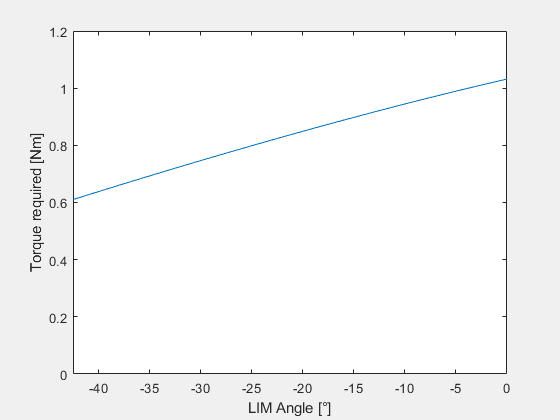


for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.2])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off

Trange(end)/2

$$ans = 0.51591622588460604094330893962494$$

%Test stall torques across stage 4 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
     L_body_centre: 0.0437
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 16.0
             N_sun: 50.0
               a11: 0.0
               a12: 0.0
               a13: 0.0
               a21: 0.0
               a22: 0.0
               a23: 0.0
               a31: 0.0
               a32: 0.0
         

solutions4 = []


solutions4 =

     []



for i = linspace(0, pi/2, 100)
    solutions4 = [solutions4; mysolver([unsolved; t13 == i; t23 == 0;], 1, sol)];
    solutions4(end).T_z
end

$$ans = 1.2503645710814432997455546716659$$

$$ans = 1.259717217304018734626629709996$$

$$ans = 1.2688956192518341861572511679256$$

$$ans = 1.2778931735736717486531862460005$$

$$ans = 1.2867031702318305155631951437012$$

$$ans = 1.2953187979178279468089942580586$$

$$ans = 1.3037331494610550362243500355017$$

$$ans = 1.3119392272260541700186370256917$$

$$ans = 1.3199299484950591535768401035839$$

$$ans = 1.3276981508333739070053291495188$$

$$ans = 1.3352365974360651864777075229167$$

$$ans = 1.3425379824553014751198351557509$$

$$ans = 1.3495949363084816728401033353638$$

$$ans = 1.3564000309680608066255153670783$$

$$ans = 1.3629457852346936880224512292007$$

$$ans = 1.3692246699959798250800312069612$$

$$ans = 1.3752291134737030233373215495629$$

$$ans = 1.3809515064630165165251432835006$$

$$ans = 1.3863842075675290958570682390119$$

$$ans = 1.3915195484346998623064083059323$$

$$ans = 1.3963498389963495275147105096856$$

$$ans = 1.4008673727194455202971698244992$$

$$ans = 1.4050644318726176220782540943203$$

$$ans = 1.4089332928141117387279630636816$$

$$ans = 1.412466231307093138526377138264$$

$$ans = 1.4156555278683685672644838898575$$

$$ans = 1.4184934731567106793893970901544$$

$$ans = 1.4209723734070398223803029009269$$

$$ans = 1.4230845559167490129538463393735$$

$$ans = 1.4248223745904495661880431997557$$

$$ans = 1.4261782155493688648356242692742$$

$$ans = 1.4271445028115497159266240413304$$

$$ans = 1.4277137040488840982646783184115$$

$$ans = 1.4278783364268642423363159973184$$

$$ans = 1.4276309725327522012784624496846$$

$$ans = 1.4269642463976565726572359153666$$

$$ans = 1.4258708596177629238956389860998$$

$$ans = 1.4243435875796937688781922560865$$

$$ans = 1.422375285794675551195455327837$$

$$ans = 1.4199588963458648264692824370331$$

$$ans = 1.4170874544528344259247487470243$$

$$ans = 1.4137540951568434626246498169174$$

$$ans = 1.4099520601301131668359412648883$$

$$ans = 1.4056747046119041911688908177955$$

$$ans = 1.4009155044737406282706483731057$$

$$ans = 1.3956680634156518976919144588459$$

$$ans = 1.3899261202948062027349205693129$$

$$ans = 1.3836835565873887168830793102855$$

$$ans = 1.3769344039840342938237700320322$$

$$ans = 1.3696728521185585544799943056819$$

$$ans = 1.3618932564291429385238086383928$$

$$ans = 1.3535901461505189786878075360113$$

$$ans = 1.3447582324350649508054528774014$$

$$ans = 1.3353924166000744952360379156807$$

$$ans = 1.3254877984977821704242794724613$$

$$ans = 1.3150396850040356235538600945901$$

$$ans = 1.3040435986207886583237128028048$$

$$ans = 1.2924952861868545449475986071021$$

$$ans = 1.2803907276906051513161586514668$$

$$ans = 1.267726145177529687245518287057$$

$$ans = 1.2544980117447779795587253739575$$

$$ans = 1.2407030606140083027443579249567$$

$$ans = 1.226338294273040092002314235027$$

$$ans = 1.2114009936759787324676625124093$$

$$ans = 1.1958887274906345859246369922888$$

$$ans = 1.1797993613812031949460834629088$$

$$ans = 1.1631310673133100880260416419165$$

$$ans = 1.1458823328676538827347045426217$$

$$ans = 1.1280519705476077295777897263791$$

$$ans = 1.1096391270652640425808689959551$$

$$ans = 1.0906432925895336167169399601188$$

$$ans = 1.0710643099390405409997695305652$$

$$ans = 1.050902383701691895829309454612$$

$$ans = 1.0301580892619494034139347948741$$

$$ans = 1.0088323817159925219519750073562$$

$$ans = 0.98692660465414268767089295629666$$

$$ans = 0.96444249878912046778055138153408$$

$$ans = 0.94138221040793544325462105582264$$

$$ans = 0.91774829962446703314353811552946$$

$$ans = 0.89354374840908771972800381153629$$

$$ans = 0.86877196837101291894449253569044$$

$$ans = 0.84343680826843889534152039534298$$

$$ans = 0.81754256122095660934402722850982$$

$$ans = 0.79109397159821028249693467703612$$

$$ans = 0.76409624155830993845866007245932$$

$$ans = 0.73655503720911245278227149510712$$

$$ans = 0.70847649436516098856715065114995$$

$$ans = 0.67986722387282338023055365660743$$

$$ans = 0.65073431647600130070690341337374$$

$$ans = 0.62108534719469909491807016844581$$

$$ans = 0.59092837918874907395501239159211$$

$$ans = 0.56027196707909379377488605834893$$

$$ans = 0.52912515969923016639817677953756$$

$$ans = 0.49749750224972972851409153357966$$

$$ans = 0.46539903782916831694560024951306$$

$$ans = 0.43284030831533075929920649024394$$

$$ans = 0.3998323545712056138756445483457$$

$$ans = 0.3663867159510547173836452951667$$

$$ans = 0.33251542908273510658656794412821$$

$$ans = 0.29823102590346906120273027686752$$

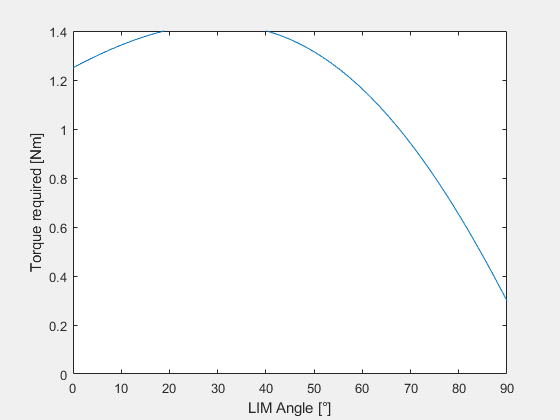


for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([0,90])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")

%Test stall torques across stage 6 movement
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_rolling; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width-0.075; s52 == rw+2*step_height;
    %Set vertical accelleration of bottom wheel to zero to solve for lifting torque
    a62 == 0;
    %Set step that contacts tail
    N2==1;
    %Set the state of the device
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)

sol = struct with fields:
       C_friction7: 0.2
         F_react53: 0.0
         F_react61: 0.0
         F_react62: 0.0
         F_react63: 0.0
         F_react73: 0.0
    F_reactPrime73: 0.0
                I1: 0.0015369319646590562551680125835674
                I2: 0.000068751841737150920660058550648586
                I3: 0.000013375817588925833023587828873868
                I4: 0.000013375817588925833023587828873868
                I5: 0.00012233851720283331582055097452866
                I6: 0.00012233851720283331582055097452866
                I7: 0.0032796810000000000025199842212942
     L_body_centre: 0.0437
         M_react61: 0.0
         M_react62: 0.0
         M_react63: 0.0
                N2: 1.0
           N_idler: 33.0
          N_planet: 16.0
             N_sun: 50.0
               a13: 0.0
               a23: 0.0
               a33: 0.0
               a43: 0.0
               a52: 0.0
               a53: 0.0
               a62: 0.0
               a63: 0.0
         

solutions6 = []


solutions6 =

     []



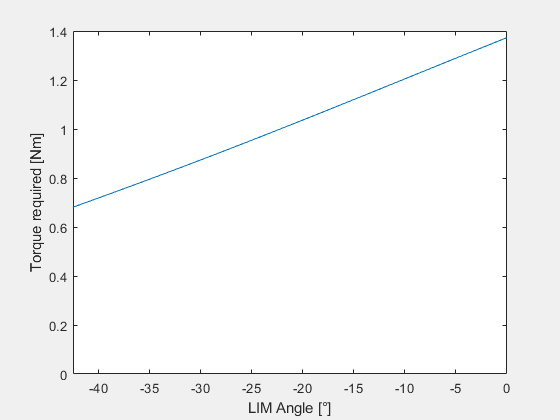

for i = linspace(-0.74188086214972967258453186960347, 0, 100)
    solutions6 = [solutions6; mysolver([unsolved; t13 == i; t23 == 0;], 1, sol)];
end

for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi;
end

plot(thetarange, Trange)
xlim([-42.5,0])
ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
hold off

Trange(end)/2

$$ans = 0.68652353552281479879266295947356$$

Plot torques across complete movement

%First movement 1
for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    thetarange(i) =solutions1(i).t13*180/pi;
end
PlotTorque = Trange;
PlotTheta = thetarange;

%Movement 2
j=linspace(90*pi/180, -0.74188086214972967258453186960347+pi, 100)

j =     1.5708    1.5792    1.5875    1.5959    1.6043    1.6127    1.6210    1.6294    1.6378    1.6462    1.6545    1.6629    1.6713    1.6796    1.6880    1.6964    1.7048    1.7131    1.7215    1.7299    1.7383    1.7466    1.7550    1.7634    1.7717    1.7801    1.7885    1.7969    1.8052    1.8136    1.8220    1.8304    1.8387    1.8471    1.8555    1.8638    1.8722    1.8806    1.8890    1.8973    1.9057    1.9141    1.9225    1.9308    1.9392    1.9476    1.9559    1.9643    1.9727    1.9811


for i = 1:100
    Trange(i) = 0;
    thetarange(i) = j(i)*180/pi;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 3
for i = 1:length(solutions3)
    Trange(i) = solutions3(i).T_z;
    thetarange(i) =solutions3(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 1 on step
for i = 1:length(solutions1)
    Trange(i) = solutions1(i).T_z;
    thetarange(i) =solutions1(i).t13*180/pi+180;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 5
j=linspace(90*pi/180+pi, -0.74188086214972967258453186960347+2*pi, 100)

j =     4.7124    4.7208    4.7291    4.7375    4.7459    4.7543    4.7626    4.7710    4.7794    4.7877    4.7961    4.8045    4.8129    4.8212    4.8296    4.8380    4.8464    4.8547    4.8631    4.8715    4.8798    4.8882    4.8966    4.9050    4.9133    4.9217    4.9301    4.9385    4.9468    4.9552    4.9636    4.9719    4.9803    4.9887    4.9971    5.0054    5.0138    5.0222    5.0306    5.0389    5.0473    5.0557    5.0641    5.0724    5.0808    5.0892    5.0975    5.1059    5.1143    5.1227


for i = 1:100
    Trange(i) = 0;
    thetarange(i) = j(i)*180/pi;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 6
for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi+360;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 5
j=linspace(90*pi/180+2*pi, -0.74188086214972967258453186960347+3*pi, 100)

j =     7.8540    7.8624    7.8707    7.8791    7.8875    7.8958    7.9042    7.9126    7.9210    7.9293    7.9377    7.9461    7.9545    7.9628    7.9712    7.9796    7.9879    7.9963    8.0047    8.0131    8.0214    8.0298    8.0382    8.0466    8.0549    8.0633    8.0717    8.0800    8.0884    8.0968    8.1052    8.1135    8.1219    8.1303    8.1387    8.1470    8.1554    8.1638    8.1722    8.1805    8.1889    8.1973    8.2056    8.2140    8.2224    8.2308    8.2391    8.2475    8.2559    8.2643


for i = 1:100
    Trange(i) = 0;
    thetarange(i) = j(i)*180/pi;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 6
for i = 1:length(solutions6)
    Trange(i) = solutions6(i).T_z;
    thetarange(i) =solutions6(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange];
PlotTheta = [PlotTheta, thetarange];

%Movement 4
for i = 1:length(solutions4)
    Trange(i) = solutions4(i).T_z;
    thetarange(i) =solutions4(i).t13*180/pi+540;
end
PlotTorque = [PlotTorque, Trange, 0];
PlotTheta = [PlotTheta, thetarange, 630];



f= figure

f =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


plot(PlotTheta, PlotTorque)
ylabel("Torque required [Nm]")
xlabel("LIM Angle [°]")
f.CurrentAxes.XTick=0:90:630

f =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [1 1 1]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


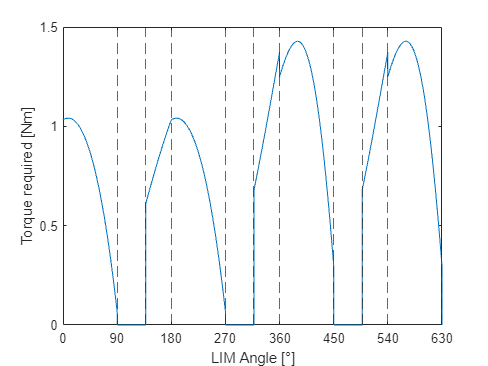

xlim([0,630])
xline(90:90:630,"--")
xline([180:180:540]-0.74188086214972967258453186960347*180/pi,"--")
hold off

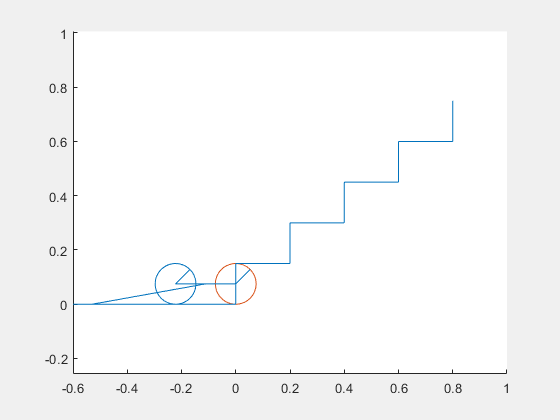

ans =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


drawfigure(solutions1(1))

testvar = vpa(PlotTheta)

%Test stall torques with varying gear ratios
%remove certain parameters
reducedParameters = setdiff(DesignParameters, assignment_gears)
%add back certain parameters, and add relation for gear separations to be
%based on gear ratios
new_assignment_gears = [%r3 == 0.027612244897959183673469387755102;
    l5_ab == 0.041+0.07;
    rw == 0.075; l7_ab == 0.425; 
    N_idler == 33; N_sun == 50; C_friction7 == 0.2;];

reducedEquations = setdiff(Core_equations, eqns_radius)

new_eqns_radius = [r2==separation23*N_sun/(N_sun+N_idler)
    r3==separation35*N_idler/(N_planet+N_idler)
    r3==separation23*N_idler/(N_idler+N_sun)
    r4==r3
    r5==separation35*N_planet/(N_planet+N_idler)
    r6==r5];

Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    reducedEquations; new_eqns_radius; reducedParameters; new_assignment_gears
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnStep; condition_wheel1locked; condition_wheel2NoContact; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 2*step_width; s52 == rw+2*step_height;
    %Set accellerations to zero to solve for stalling torque
    unwrap_y(a == 0)
    %Set the state of the device
    %Set step that contacts tail
    N2==1;
    t23 == 0;
    tv13 == 0; tv23 == 0;
    ];
[sol, unsolved] = mysolver(Eqns, 0)
T_max = [];
solutionset = [];
for j = 1:60
    Trange = []
    solutionsGR = []
    theta=linspace(0.4, 0.5, 10)
    [sol2, unsolved2]= mysolver([unsolved; N_planet == j], 0, sol);
    for i = 1:length(theta)
        solutionsGR = [solutionsGR; mysolver([unsolved2; t13 == theta(i)], 1, sol2)];
        Trange(i) = solutionsGR(i).T_z;
    end
    j
    [Tmax(j),idx] = max(Trange);
    solutionset = [solutionset; solutionsGR(idx)];
    T_max
    idx
end


plot(1:60, Tmax)
% xlim([-42.5,0])
% ylim([0, 1.4])
ylabel("Torque required [Nm]")
xlabel("Gear ratio")
hold off


Create an animation by using the Runge Kutta method for discrete ODE solution

%Motor torque is not constant, create function to determine motor torque
%based on speed and voltage
motor_stallTorque = 6; % Nm
motor_NLSpeed = 0.6; %rad/s
syms speed stallTorque voltage 
eqns_motor = [
    speed == tv23;
    T_z == 2*motor_stallTorque*(voltage/12.0-speed/motor_NLSpeed)
    stallTorque == motor_stallTorque*(voltage/12.0)]

%Incomplete solution for movement1
Eqns=[
    %Load Core equations (sum of forces, moments, kinematics)
    Core_equations; DesignParameters
    %Load conditional equations for specified movement
    condition_2d; condition_tailOnGround; condition_wheel1locked; condition_wheel2NoContact; eqns_motor; condition_angle_quadrants;
    %Set position of front wheel
    s51 == 0; s52 == rw;
    %Set Motor voltage 
    stallTorque == 6;
    ];

[sol, unsolved] = mysolver(Eqns, 0);

Eqns=[unsolved;
    t13 == 0; t23 ==0 
    tv13 == 0; tv23 == 0;
    ]; 
[sol2, unsolved2] = mysolver(Eqns, 1, sol)


%Start calculations
framesol = []
frameeqs = unsolved
Step_Value = 0.005;
t_beg = 0;
t_end = 10;
t_intial=0;
u_intial=[sol2.t13,sol2.t23,sol2.tv13,sol2.tv23];
% Routine starts here
h=Step_Value;
t=t_beg:h:t_end;
u=zeros(4,length(t));
u(:,1)=u_intial;




for i=1:(length(t)-1)
    t0=t(i);
    up1=u(1,i); %t13
    up2=u(2,i); %t23
    up3=u(3,i); %tv13
    up4=u(4,i); %tv23
    framesol = [framesol; mysolver([unsolved; t13 == up1; t23 == up2; tv13 == up3; tv23 == up4;], 1)];
    k1 = [framesol(i).tv13; framesol(i).tv23; framesol(i).ta13; framesol(i).ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k1(1); t23 == up2+0.5*h*k1(2); tv13 == up3+0.5*h*k1(3); tv23 == up4+0.5*h*k1(4);], 1);
    k2 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+0.5*h*k2(1); t23 == up2+0.5*h*k2(2); tv13 == up3+0.5*h*k2(3); tv23 == up4+0.5*h*k2(4);], 1);
    k3 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    tempsol = mysolver([unsolved; t13 == up1+k3(1)*h; t23 == up2+k3(2)*h; tv13 == up3+k3(3)*h; tv23 == up4+k3(4)*h], 1);
    k4 = [tempsol.tv13; tempsol.tv23; tempsol.ta13; tempsol.ta23];
    u(:,i+1) = u(:,i) + (h/6)*(k1+2*k2+2*k3+k4);
    i
end

f = fieldnames(sol)
nframes = length(framesol)
for i = 1:length(f)
    for j = 1:nframes
        framesol(j).(f{i}) = sol.(f{i});
    end
end

F(length(framesol)) = struct('cdata',[],'colormap',[]);
for j=1:length(framesol)
    f=figure('visible','off');
    hold on;
    %wheels
    circle(framesol(j).s61, framesol(j).s62, framesol(j).rw);
    line([framesol(j).s61,framesol(j).s61+framesol(j).rw*cos(-framesol(j).t63+pi/4)],[framesol(j).s62,framesol(j).s62+framesol(j).rw*sin(-framesol(j).t63+pi/4)])
    
    circle(framesol(j).s51, framesol(j).s52, framesol(j).rw);
    line([framesol(j).s51,framesol(j).s51+framesol(j).rw*cos(-framesol(j).t53+pi/4)],[framesol(j).s52,framesol(j).s52+framesol(j).rw*sin(-framesol(j).t53+pi/4)])
    
    %frame
    line([framesol(j).s51,framesol(j).s61],[framesol(j).s52,framesol(j).s62])
    
    %Tail
    line([framesol(j).s11,framesol(j).s7End1],[framesol(j).s12,framesol(j).s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [framesol(j).step_start1-10; framesol(j).step_start2];
    for i= 1:5
        corner(:,2*i) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i-1)];
        corner(:,2*i+1) =  [framesol(j).step_start1+framesol(j).step_width*(i-1); framesol(j).step_start2+framesol(j).step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
    F(j) = getframe(gcf);
end

fig = figure;



movie(fig, F, 1, 1/h);



f=figure('visible','on');
hold on;
%wheels
circle(sol.s61, sol.s62, sol.rw);
line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])

circle(sol.s51, sol.s52, sol.rw);
line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])

%frame
line([sol.s51,sol.s61],[sol.s52,sol.s62])

%Tail
line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])

axis equal;
xlim([-0.6,1])
%ylim([-0.1, 0.5])
%step
corner(:,1) = [sol.step_start1-10; sol.step_start2];
for i= 1:5
    corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
    corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
end
line(corner(1,:), corner(2,:))
% line([sol.step_start1-10, sol.step_start1], [sol.step_start2,sol.step_start2])
% line([sol.step_start1, sol.step_start1], [sol.step_start2, sol.step_start2+ sol.step_height])
% line([sol.step_start1, sol.step_start1+sol.step_width], [sol.step_height, sol.step_height])
hold off;



function f = drawfigure(sol)
    f=figure('visible','on');
    hold on;
    %wheels
    circle(sol.s61, sol.s62, sol.rw);
    line([sol.s61,sol.s61+sol.rw*cos(-sol.t63+pi/4)],[sol.s62,sol.s62+sol.rw*sin(-sol.t63+pi/4)])
    
    circle(sol.s51, sol.s52, sol.rw);
    line([sol.s51,sol.s51+sol.rw*cos(-sol.t53+pi/4)],[sol.s52,sol.s52+sol.rw*sin(-sol.t53+pi/4)])
    
    %frame
    line([sol.s51,sol.s61],[sol.s52,sol.s62])
    
    %Tail
    line([sol.s11,sol.s7End1],[sol.s12,sol.s7End2])
    
    axis equal;
    xlim([-0.6,1])
    %ylim([-0.1, 0.5])
    %step
    corner(:,1) = [sol.step_start1-10; sol.step_start2];
    for i= 1:5
        corner(:,2*i) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i-1)];
        corner(:,2*i+1) =  [sol.step_start1+sol.step_width*(i-1); sol.step_start2+sol.step_height*(i)];
    end
    line(corner(1,:), corner(2,:))
    hold off;
end

function h = circle(x,y,r)
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit);
end